## boxcharts to compare the muscles in each position between sexes

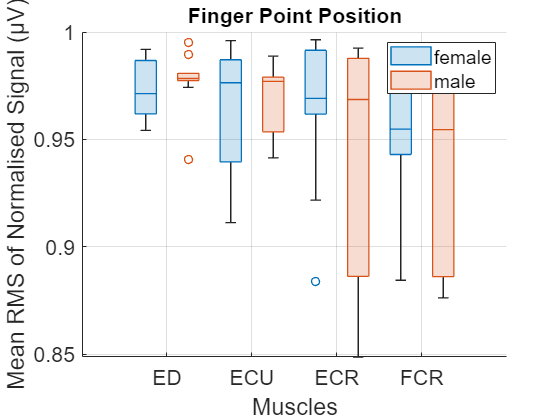

% finger point
clear boxchart
data = readtable('box_charts.xlsx','Sheet','Sheet1');
muscle_order = {'ED','ECU','ECR','FCR'};
data.Muscle = categorical(data.Muscle,muscle_order);
sex = {'female', 'male'};
data.sex = categorical(data.sex,sex);

figure(1)
boxchart(data.Muscle, data.mean,'GroupByColor',data.sex)
grid on
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Muscles','FontSize',16)
ax = gca;
ax.FontSize = 16;
legend
title('Finger Point Position','FontSize',16)

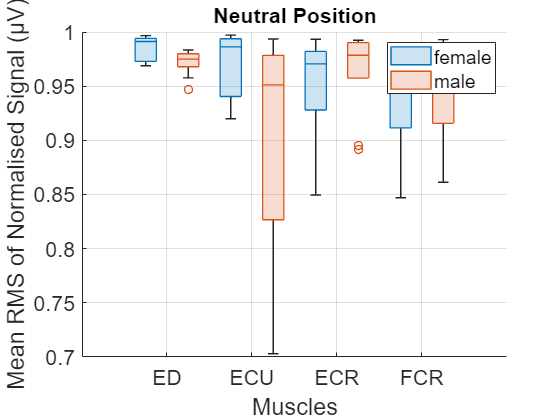

% neutral
clear boxchart
data = readtable('box_charts.xlsx','Sheet','Sheet2');
muscle_order = {'ED','ECU','ECR','FCR'};
data.Muscle = categorical(data.Muscle,muscle_order);
sex = {'female', 'male'};
data.sex = categorical(data.sex,sex);

figure(2)
boxchart(data.Muscle, data.mean,'GroupByColor',data.sex)
grid on
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Muscles','FontSize',16)
ax = gca;
ax.FontSize = 16;
legend
title('Neutral Position','FontSize',16)

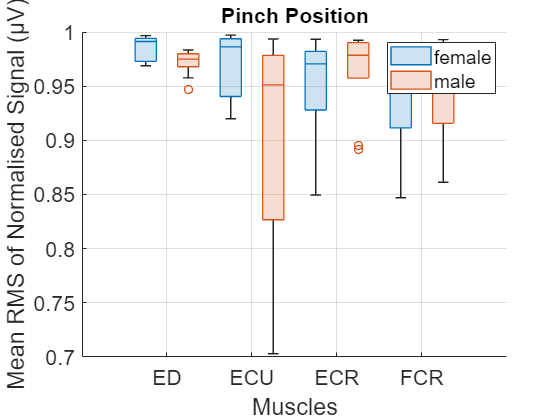

% pinch
clear boxchart
data = readtable('box_charts.xlsx','Sheet','Sheet2');
muscle_order = {'ED','ECU','ECR','FCR'};
data.Muscle = categorical(data.Muscle,muscle_order);
sex = {'female', 'male'};
data.sex = categorical(data.sex,sex);

figure(3)
boxchart(data.Muscle, data.mean,'GroupByColor',data.sex)
grid on
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Muscles','FontSize',16)
ax = gca;
ax.FontSize = 16;
legend
title('Pinch Position','FontSize',16)


fig3 = figure(3);

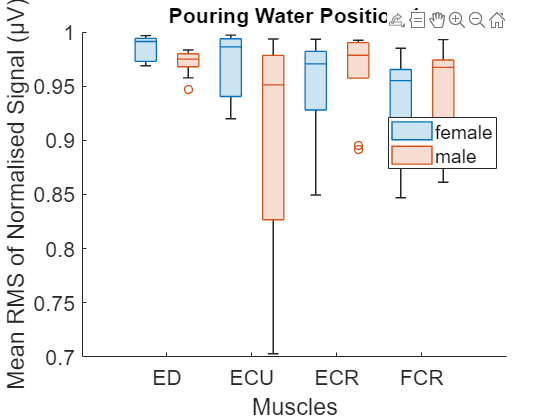

% pour water position 1
clear boxchart
data = readtable('box_charts.xlsx','Sheet','Sheet2');
muscle_order = {'ED','ECU','ECR','FCR'};
data.Muscle = categorical(data.Muscle,muscle_order);
sex = {'female', 'male'};
data.sex = categorical(data.sex,sex);

figure(4)
grid on
boxchart(data.Muscle, data.mean,'GroupByColor',data.sex)
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Muscles','FontSize',16)
ax = gca;
ax.FontSize = 16;
legend
title('Pouring Water Position 1','FontSize',16)

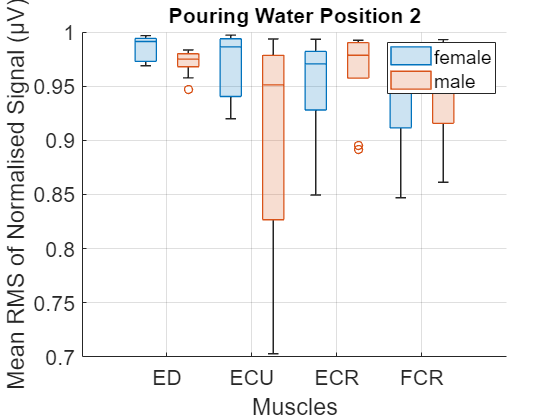


% pour water position 2
clear boxchart
data = readtable('box_charts.xlsx','Sheet','Sheet2');
muscle_order = {'ED','ECU','ECR','FCR'};
data.Muscle = categorical(data.Muscle,muscle_order);
sex = {'female', 'male'};
data.sex = categorical(data.sex,sex);

figure(5)
boxchart(data.Muscle, data.mean,'GroupByColor',data.sex)
grid on
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Muscles','FontSize',16)
ax = gca;
ax.FontSize = 16;
legend
title('Pouring Water Position 2','FontSize',16)

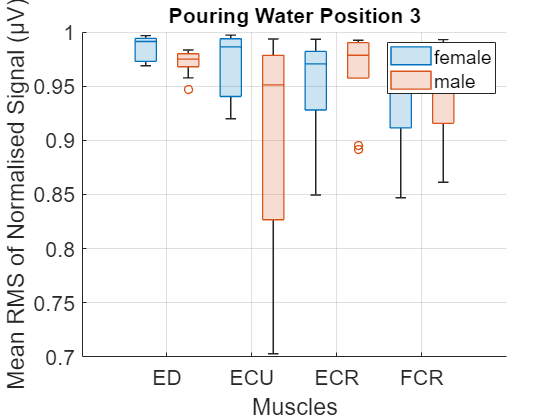


% pour water position 3
clear boxchart
data = readtable('box_charts.xlsx','Sheet','Sheet2');
muscle_order = {'ED','ECU','ECR','FCR'};
data.Muscle = categorical(data.Muscle,muscle_order);
sex = {'female', 'male'};
data.sex = categorical(data.sex,sex);

figure(6)
boxchart(data.Muscle, data.mean,'GroupByColor',data.sex)
grid on
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Muscles','FontSize',16)
ax = gca;
ax.FontSize = 16;
legend
title('Pouring Water Position 3','FontSize',16)

## boxcharts to compare the muscles according to the poition between sexes

% these values need to be cleared to avoid errors when plotting the
% boxcharts. This is because some subjects did not have recordings for
% certain muscles, which would affect the calculus used in the next
% section.

female = xlsread("female.xlsx");
male = xlsread("male.xlsx");
clear female_ed_fp
clear female_ed_ne
clear female_ed_pi

clear female_ed_pw1
clear female_ed_pw2
clear female_ed_pw3

clear male_ecu_fp
clear male_ecu_ne
clear male_ecu_pi

clear male_ecr_pw1
clear male_ecu_pw2
clear male_ecu_pw3



clear female_ed_fp
clear female_ed_ne
clear female_ed_pi

clear female_ed_pw1
clear female_ed_pw2
clear female_ed_pw3

clear male_ecu_fp
clear male_ecu_ne
clear male_ecu_pi

clear male_ecr_pw1
clear male_ecu_pw2
clear male_ecu_pw3

female = xlsread("female.xlsx");
male = xlsread("male.xlsx");
% common range where the data is in the table
f = 1:10;
m = 1:10;

% range execptions for muscle which does not have data for certain
% participants
f_ed1 = 1:6;
f_ed2 = 10;
m_ecu1 = 1:2;
m_ecu2 = 4:10;
f_pw_r = 1:6;
f_pw_r2 = 8:10;

female_ed_fp = [female(f_ed1,1);female(f_ed2,1)];
female_ecu_fp = female(f,2);
female_ecr_fp = female(f,3);
female_fcr_fp = female(f,4);

female_ed_ne = [female(f_ed1,5);female(f_ed2,5)];
female_ecu_ne = female(f,6);
female_ecr_ne = female(f,7);
female_fcr_ne = female(f,8);

female_ed_pi = [female(f_ed1,9);female(f_ed2,9)];
female_ecu_pi = female(f,10);
female_ecr_pi = female(f,11);
female_fcr_pi = female(f,12);

female_ed_pw1 = [female(f_ed1,13);female(f_ed2,13)];
female_ecu_pw1 = [female(f_pw_r,14);female(f_pw_r2,14)];
female_ecr_pw1 = [female(f_pw_r,15);female(f_pw_r2,15)];
female_fcr_pw1 = [female(f_pw_r,16);female(f_pw_r2,16)];

female_ed_pw2 = [female(f_ed1,17);female(f_ed2,17)];
female_ecu_pw2 = [female(f_pw_r,18);female(f_pw_r2,18)];
female_ecr_pw2 = [female(f_pw_r,19);female(f_pw_r2,19)];
female_fcr_pw2 = [female(f_pw_r,20);female(f_pw_r2,20)];

female_ed_pw3 = [female(f_ed1,21);female(f_ed2,21)];
female_ecu_pw3 = [female(f_pw_r,22);female(f_pw_r2,22)];
female_ecr_pw3 = [female(f_pw_r,23);female(f_pw_r2,23)];
female_fcr_pw3 = [female(f_pw_r,24);female(f_pw_r2,24)];

male_ed_fp = male(m,1);
male_ecu_fp = [male(m_ecu1,2); male(m_ecu2,2)];
male_ecr_fp = male(m,3);
male_fcr_fp = male(m,4);

male_ed_ne = male(m,5);
male_ecu_ne = [male(m_ecu1,6); male(m_ecu2,6)];
male_ecr_ne = male(m,7);
male_fcr_ne = male(m,8);

male_ed_pi = male(m,9);
male_ecu_pi = [male(m_ecu1,10); male(m_ecu2,10)];
male_ecr_pi = male(m,11);
male_fcr_pi = male(m,12);

male_ed_pw1 = male(m,13);
male_ecu_pw1 = [male(m_ecu1,14); male(m_ecu2,14)];
male_ecr_pw1 = male(m,15);
male_fcr_pw1 = male(m,16);

male_ed_pw2 = male(m,17);
male_ecu_pw2 = [male(m_ecu1,14); male(m_ecu2,14)];
male_ecr_pw2 = male(m,19);
male_fcr_pw2 = male(m,20);

male_ed_pw3 = male(m,21);
male_ecu_pw3 = [male(m_ecu1,22); male(m_ecu2,22)];
male_ecr_pw3 = male(m,23);
male_fcr_pw3 = male(m,24);

## Box charts comparing muscles during the different tasks

IMPORTANT TO RUN THE PREVIOUS SECTION EVERYTIME WE WANT TO RUN THIS SECTION

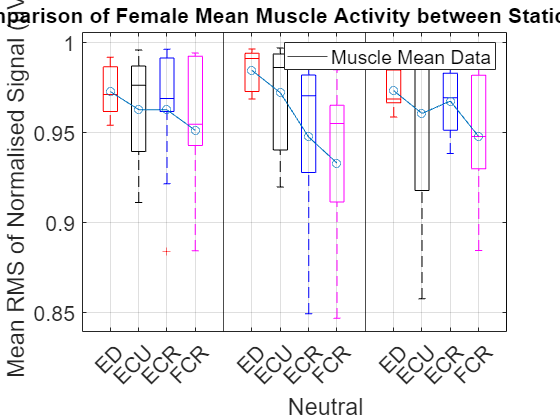

clear boxplotGroup

ed_female = [female_ed_fp female_ed_ne female_ed_pi];
ecu_female = [female_ecu_fp female_ecu_ne female_ecu_pi];
ecr_female = [female_ecr_fp female_ecr_ne female_ecr_pi];
fcr_female = [female_fcr_fp female_fcr_ne female_fcr_pi];


x = {ed_female,ecu_female,ecr_female,fcr_female};
clear mean
mean_t = [mean(female_ed_fp) mean(female_ecu_fp) mean(female_ecr_fp) mean(female_fcr_fp) NaN mean(female_ed_ne) mean(female_ecu_ne) mean(female_ecr_ne) mean(female_fcr_ne) NaN mean(female_ed_pi) mean(female_ecu_pi) mean(female_ecr_pi) mean(female_fcr_pi)];



figure(7)
boxplotGroup(x,'grouplines',true,'PrimaryLabels',{'ED','ECU','ECR','FCR'},'Colors','rkbmyg','GroupType','betweenGroups','DataLim',[0.84, 1])
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Finger Point                                                      Neutral                                                       Pinch','FontSize',16)
ax = gca;
ax.FontSize = 16;
title('Comparison of Female Mean Muscle Activity between Static Tasks','FontSize',16)
hold on
plot(mean_t,'-o')
hold off
legend ("Muscle Mean Data")
grid on

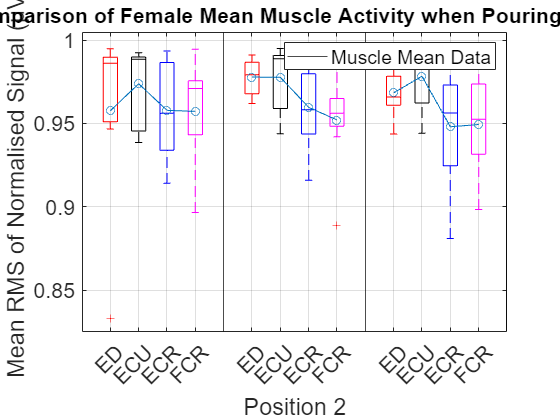



ed_female_pw = [female_ed_pw1 female_ed_pw2 female_ed_pw3];
ecu_female_pw = [female_ecu_pw1 female_ecu_pw2 female_ecu_pw3];
ecr_female_pw = [female_ecr_pw1 female_ecr_pw2 female_ecr_pw3];
fcr_female_pw = [female_fcr_pw1 female_fcr_pw2 female_fcr_pw3];


x_pw = {ed_female_pw,ecu_female_pw,ecr_female_pw,fcr_female_pw};
clear mean
mean_pw = [mean(female_ed_pw1) mean(female_ecu_pw1) mean(female_ecr_pw1) mean(female_fcr_pw1) NaN mean(female_ed_pw2) mean(female_ecu_pw2) mean(female_ecr_pw2) mean(female_fcr_pw2) NaN mean(female_ed_pw3) mean(female_ecu_pw3) mean(female_ecr_pw3) mean(female_fcr_pw3)];



figure(8)
boxplotGroup(x_pw,'grouplines',true,'PrimaryLabels',{'ED','ECU','ECR','FCR'},'Colors','rkbmyg','GroupType','betweenGroups','DataLim',[0.80, 1])
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Position 1                                                      Position 2                                                      Position 3','FontSize',16)
ax = gca;
ax.FontSize = 16;
title('Comparison of Female Mean Muscle Activity when Pouring Water','FontSize',16)
hold on
plot(mean_pw,'-o')
hold off
legend ("Muscle Mean Data")
grid on

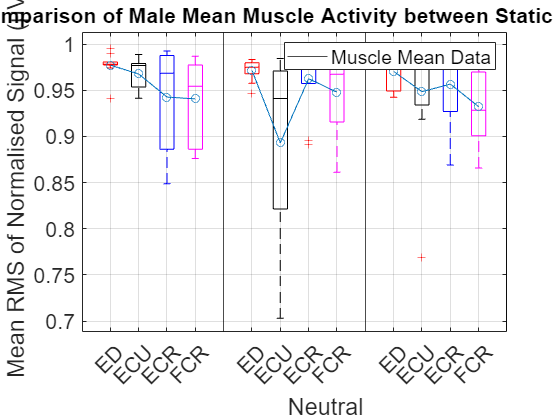




ed_male = [male_ed_fp male_ed_ne male_ed_pi];
ecu_male = [male_ecu_fp male_ecu_ne male_ecu_pi];
ecr_male = [male_ecr_fp male_ecr_ne male_ecr_pi];
fcr_male = [male_fcr_fp male_fcr_ne male_fcr_pi];


x = {ed_male,ecu_male,ecr_male,fcr_male};
clear mean
mean_t_male = [mean(male_ed_fp) mean(male_ecu_fp) mean(male_ecr_fp) mean(male_fcr_fp) NaN mean(male_ed_ne) mean(male_ecu_ne) mean(male_ecr_ne) mean(male_fcr_ne) NaN mean(male_ed_pi) mean(male_ecu_pi) mean(male_ecr_pi) mean(male_fcr_pi)];

clear legend

figure(9)
boxplotGroup(x, 'grouplines',true, 'PrimaryLabels',{'ED','ECU','ECR','FCR'},'Colors','rkbmyg','GroupType','betweenGroups')
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Finger Point                                                      Neutral                                                       Pinch','FontSize',16)
ax = gca;
ax.FontSize = 16;
title('Comparison of Male Mean Muscle Activity between Static Tasks','FontSize',16)
hold on
plot(mean_t_male,'-o')
hold off
legend("Muscle Mean Data")
grid on

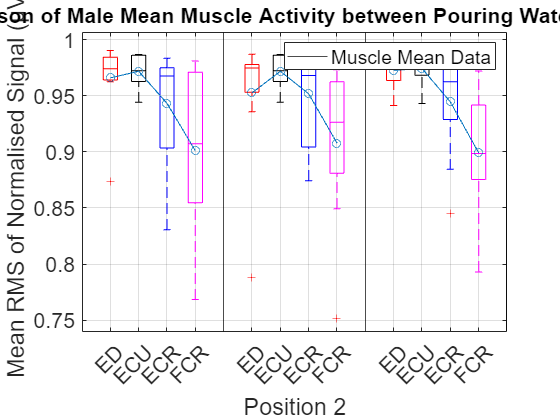





ed_male_pw = [male_ed_pw1 male_ed_pw2 male_ed_pw3];
ecu_male_pw = [male_ecu_pw1 male_ecu_pw2 male_ecu_pw3];
ecr_male_pw = [male_ecr_pw1 male_ecr_pw2 male_ecr_pw3];
fcr_male_pw = [male_fcr_pw1 male_fcr_pw2 male_fcr_pw3];


x_pw = {ed_male_pw,ecu_male_pw,ecr_male_pw,fcr_male_pw};
clear mean
mean_pw_male = [mean(male_ed_pw1) mean(male_ecu_pw1) mean(male_ecr_pw1) mean(male_fcr_pw1) NaN mean(male_ed_pw2) mean(male_ecu_pw2) mean(male_ecr_pw2) mean(male_fcr_pw2) NaN mean(male_ed_pw3) mean(male_ecu_pw3) mean(male_ecr_pw3) mean(male_fcr_pw3)];



figure(10)
boxplotGroup(x_pw,'grouplines',true,'PrimaryLabels',{'ED','ECU','ECR','FCR'},'Colors','rkbmyg','GroupType','betweenGroups','DataLim',[0.75, 1])
ylabel('Mean RMS of Normalised Signal (μV)','FontSize',16)
xlabel('Position 1                                                      Position 2                                                      Position 3','FontSize',16)
ax = gca;
ax.FontSize = 16;
title('Comparison of Male Mean Muscle Activity between Pouring Water Positions','FontSize',16)
hold on
plot(mean_pw_male,'-o')
hold off
legend("Muscle Mean Data")
grid on